# Load data

This script parses a derived parameter file, filters out soundings missing necessary information, saves the filtered soundings to a MAT file for future use, chooses one sounding and extracts only the data needed for the Simulink model. The derived parameter file should only be parsed once.  The saved .mat file can be loaded in subsequent runs of the model.  The sounding is plotted and the model loads its data from the workspace. 

## Parse, filter and save soundings

% Only do this once per file.

% Parse derived parameter file
parsed_soundings = parse_derived('test_data.txt');

% Filter soundings based on the presence of the mixed layer height parameter
filtered_soundings = filter_soundings(parsed_soundings);

% Save the filtered_soundings variable to a MAT file for future use
save('filtered_soundings.mat', 'filtered_soundings');


## Extract necessary data for Simulink


% Load the saved variable from the MAT file in Simulink
load('filtered_soundings.mat');

% Extract and return only the relevant data in the chosen sounding
reduced_sounding = extract_sounding_data(filtered_soundings(4));

% Remove all measurements that have a geopotential height REPGPH
% greater than 1.3 times the mixed layer height.
reduced_sounding = remove_values_above(reduced_sounding, 1.3);

max_height interpreted as a factor



% Interpolate missing values in the reduced sounding
reduced_sounding = interpolate_missing(reduced_sounding);


% Convert the sounding object into a Simulink bus object of the type
% sounding_bus (defined in sounding_bus.mat)

numLevels = length(reduced_sounding.derived.REPGPH); % This variable needs to be
                                                     % present in the workspace
sounding_data_bus.numLevels = numLevels
sounding_data_bus.zi = reduced_sounding.mixedLayerHeight;
sounding_data_bus.LCL = reduced_sounding.LCLheight;
sounding_data_bus.REPGPH = reduced_sounding.derived.REPGPH;
sounding_data_bus.PRESS = reduced_sounding.derived.PRESS;
sounding_data_bus.TEMP = reduced_sounding.derived.TEMP;
sounding_data_bus.PTEMP = reduced_sounding.derived.PTEMP;
sounding_data_bus.VTEMP = reduced_sounding.derived.VTEMP;
sounding_data_bus.VAPPRESS = reduced_sounding.derived.VAPPRESS;
sounding_data_bus.SATVAP = reduced_sounding.derived.SATVAP;
sounding_data_bus.REPRH = reduced_sounding.derived.REPRH;


## Plot atmospheric profiles

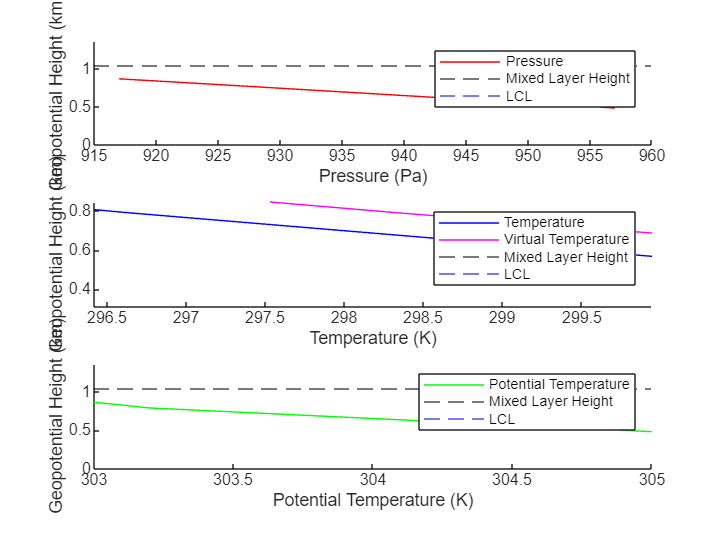

% Plot pressure, temperature, potential temperature and virtual 
% temperature profiles over geopotential height. The geopotential 
% height is used as the vertical coordinate.
plot_sounding(reduced_sounding, 1.3);